% load file and variables score1, pass1; classA, classB
file = matfile('Homework5.mat');
score = file.score1;
pass = file.pass1;

classA = file.classA;
classB = file.classB;

## 1. The `score1 `variable contains scores received by 100 students on some test. The `pass1 `variable contains 0s or 1s indicating whether each student ended up passing the course. Visualize these data using a scatter plot. Now suppose we want to use logistic regression to predict whether a student passes the course based on his/her score. Our model is *f(score) = 1/(1+exp(-(a*score+b)) *where *a *and *b *are free parameters. Suppose *a *is 1 and *b *is –72. Plot this model on the scatter plot using a red line. Then calculate the likelihood of the data points under this model and report this to the command window. Now suppose *a *is 0.5 and *b *is –32. Plot this model on the scatter plot using a blue line, and report the likelihood of the data points under this model to the command window. Which of the two models results in the higher likelihood? For the model with the higher likelihood, what is the percentage of data points correctly classified?

% divide passed and failed results
passed = score(pass == 1);
failed = score(pass == 0);

fprintf('mean for passed: %g', mean(passed));

mean for passed: 79.0168

fprintf('mean for failed: %g', mean(failed));

mean for failed: 63.4393

fprintf('min for passed: %g', min(passed));

min for passed: 69.5167

fprintf('max for failed: %g', max(failed));

max for failed: 75.2429

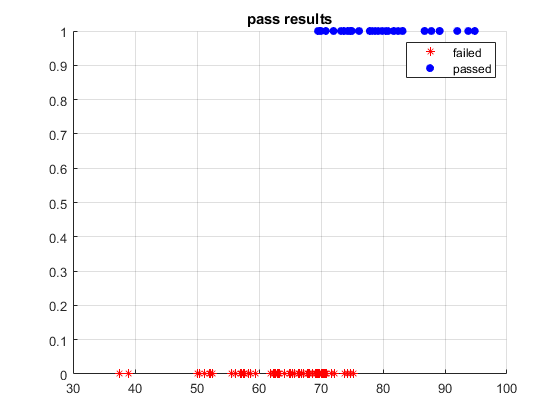

% visualise
figure;
hold on;
grid;

% display results
scatter(failed, zeros(1, length(failed)), 'r*');
scatter(passed, ones(1, length(passed)), 'bo', 'filled');
legend('failed', 'passed');
title('pass results');

ax = axis;
x = linspace(ax(1), ax(2), 100);

% f(score) = 1/(1+exp(-(a*score+b));
modelfunc = @(score, coeff) 1 ./ (1 + exp(-1 * (coeff(1) * score + coeff(2))));

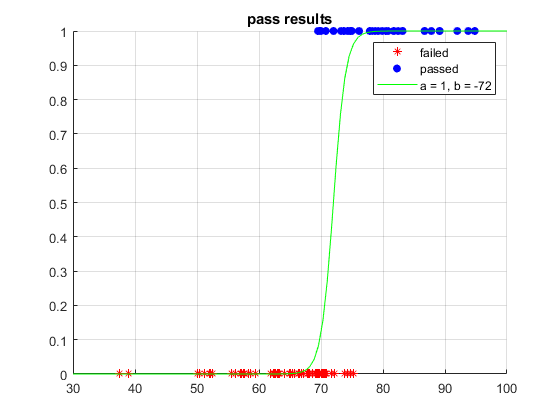

a = 1;
b = -72;
y = modelfunc(x, [a b]);
plot(x, y, 'g-');
legend('failed', 'passed', 'a = 1, b = -72');

% calculate and output the likelihood of the data points
%{
y - the output of the logistic regression model;
the likelihood that the output variable is 1 - is y,
the likelihood that the output variable is 0 - is 1 – y.
probabilistic interpretation of the data 
-> we can use maximum likelihood estimation to fit the parameters of the model (the wi terms).

(prod of samplesize count elements)
likelihood(d | m) = prod[p(dj)] = prod [yj^dj*(1-yj)^(1-dj)], where
d - the data, m - the model, dj - jth datapoint (with value 0 or 1), 
yj - output of the model for jth datapoint
%}

% Evaluate the model on the score sample
m1 = modelfunc(score, [a b]);

% like1 = 1;
% for i = 1 : length(score)
%     like1 = like1 * m1(i)^pass(i) * (1-m1(i))^(1-pass(i));
% end
likelihood1 = prod((m1 .^ pass) .* ((1 - m1) .^ (1 - pass)));

% calculate percent of correct predictions, achieved by the model
modelfit1 = (m1 >= 0.5);
accuracy1 = sum(modelfit1 == pass) / length(pass) * 100;

fprintf('Likelihood of the model with a=%g, b=%g is %s', a, b, likelihood1);

Likelihood of the model with a=1, b=-72 is 2.950917e-11

fprintf('Accuracy for the model with a=%g, b=%g is %g%%', a, b, accuracy1);

Accuracy for the model with a=1, b=-72 is 91%

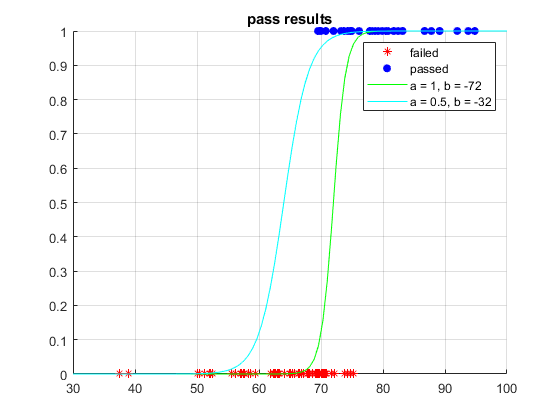

a = 0.5;
b = -32;
y = modelfunc(x, [a b]);
plot(x, y, 'c-');
legend('failed', 'passed', 'a = 1, b = -72', 'a = 0.5, b = -32');

% Evaluate the model on the score sample
m2 = modelfunc(score, [a b]);

likelihood2 = prod((m2 .^ pass) .* ((1 - m2) .^ (1 - pass)));

% calculate percent of correct predictions, achieved by the model
modelfit2 = (m2 >= 0.5);
accuracy2 = sum(modelfit2 == pass) / length(pass) * 100;

fprintf('Likelihood of the model with a=%g, b=%g is %s', a, b, likelihood2);

Likelihood of the model with a=0.5, b=-32 is 2.437698e-44

fprintf('Accuracy for the model with a=%g, b=%g is %g%%', a, b, accuracy2);

Accuracy for the model with a=0.5, b=-32 is 64%

% compare the likelihood for models
if (likelihood1 > likelihood2)
    fprintf('Likelihood and accuracy of the 1st model is higher.');
else
    fprintf('Likelihood and accuracy of the 2nd model is higher.');
end

Likelihood and accuracy of the 1st model is higher.

## 2. The `classA `and `classB `variables each contain measurements of 1,000 subjects on three different dimensions. How well can we classify whether a subject belongs to class A or class B based on measurement of the three dimensions? To answer this question, use linear discriminant analysis (LDA) to perform classification, and specifically, use leave-one-out cross-validation to obtain unbiased estimates of classification accuracy. For what percentage of subjects does LDA successfully predict class assignment?

%{
1) model the distribution of the two classes
2) then determine the decision boundary. 
two classes are characterized by multivariate Gaussian distributions with equal covariances 
(but unequal means). 
3) estimate the means of the two distributions, the common covariance of the distributions, 
the decision boundary that optimally separates the distributions is derived. 

LDA (a generative classifier) models the distributions of the two classes 
(and can therefore generate samples from each class).
Logistic regression and SVM (discriminative classifiers) directly determine 
the decision boundary (don't model the class distributions). 
%}

lengthA = size(classA, 1);
lengthB = size(classB, 1);

% construct regressor matrix - all the data, matrix [2000x3]
X = [classA; classB];

% construct data matrix 
% (correct results of prediction: 0 - classA, 1 - classB)
y = [zeros(lengthA, 1); ones(lengthB, 1)];

% init predictions vector with zero-values (all values from one class)
prediction = zeros(lengthA + lengthB, 1);

% perform leave-one-out cross-validation 
% (one values for testing - save presult of prediction)
for p = 1 : length(y)
    % training and testing indices
    ixTrain = setdiff(1 : length(y), p);
    ixTest = p;
    
    % train on the data points in ixTrain and 
    % predict the class assignment for the data points in ixTest;
    % save the result of class prediction - 0 or 1
    prediction(ixTest) = ...
        classify(X(ixTest, :), X(ixTrain, :), y(ixTrain), 'linear');
end

% calculate and output percent of correct predictions
correct = sum(prediction == y) / length(y) * 100;
fprintf('Correct predictions percent is: %.1f%%', correct);

Correct predictions percent is: 77.1%